%load data and trim data
clear 
load('10-24-24mM-try2.mat', 'permeate_flowrate_list','batch_flowrate_list', 'time_list');
%permeate_flowrate_list = permeate_flowrate_list(1:10000);
%time_list = time_list(1:10000);
permeate_flowrate_list_filtered = lowpass(permeate_flowrate_list,.1);

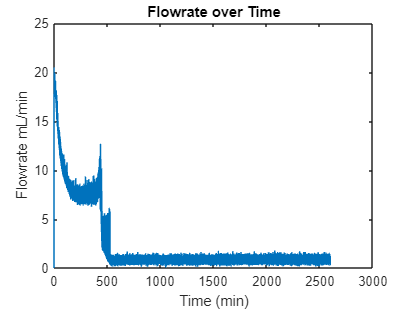

%plot original data
plot(time_list(1:end-1)/60 ,permeate_flowrate_list)
title('Flowrate over Time')
xlabel('Time (min)')
ylabel('Flowrate mL/min')

%xlim([0, 1.27e4/60])

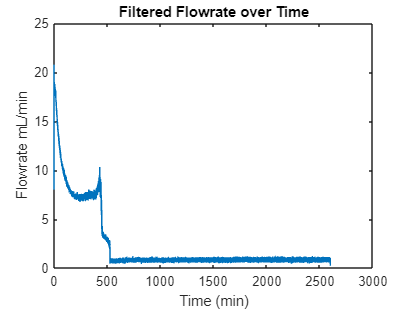

%plot filtered data
plot(time_list(1:end-1)/60, permeate_flowrate_list_filtered)
title('Filtered Flowrate over Time')
xlabel('Time (min)')
ylabel('Flowrate mL/min')

%xlim([0, 1.27e4/60])

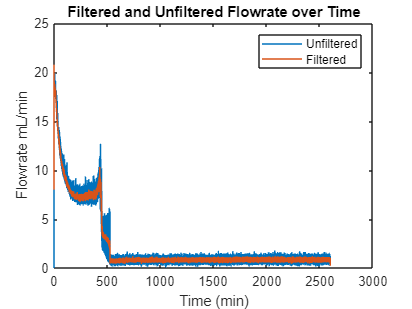

%plot both data sets
plot(time_list(1:end-1)/60, [permeate_flowrate_list, permeate_flowrate_list_filtered])
title('Filtered and Unfiltered Flowrate over Time')
xlabel('Time (min)')
ylabel('Flowrate mL/min')
legend('Unfiltered', 'Filtered')

%xlim([0, 1.27e4/60])

%snips the end of the data
for i = 1:5:size(permeate_flowrate_list_filtered)
    if mean(permeate_flowrate_list_filtered(i:i+5)) < 1
        permeate_flowrate_list_filtered_cut = permeate_flowrate_list_filtered(1:i+1000);
        time_list_cut = time_list(1:i+1000);

        break
    end
end

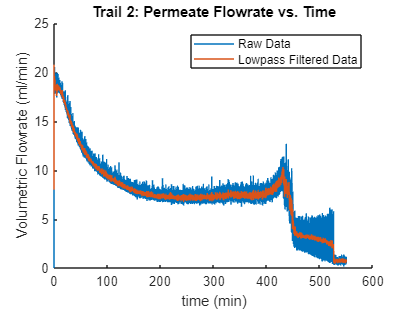

%plots new snipped data
clf;
hold on
plot(time_list_cut/60, [permeate_flowrate_list(1:size(permeate_flowrate_list_filtered_cut,1)), permeate_flowrate_list_filtered_cut])
title("Trail 2: Permeate Flowrate vs. Time")
xlabel("time (min)")
ylabel('Volumetric Flowrate (ml/min)')
legend('Raw Data','Lowpass Filtered Data', 'Location', 'northeast')
hold off

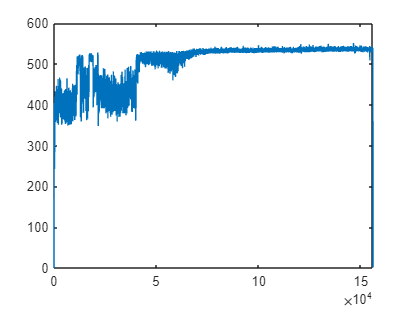

clf;
plot(time_list(1:end-1), batch_flowrate_list)

batch12 = load("11-16-24mM-try12.mat", 'time_list', 'permeate_flowrate_list');
batch14 = load('11-19-24mM-try14.mat', 'time_list', 'permeate_flowrate_list');
batch16 = load('11-26-24mM-try16.mat', 'time_list', 'permeate_flowrate_list');

batch12.permeate_flowrate_filtered = lowpass(batch12.permeate_flowrate_list, .1);
batch14.permeate_flowrate_filtered = lowpass(batch14.permeate_flowrate_list, .1);
batch16.permeate_flowrate_filtered = lowpass(batch16.permeate_flowrate_list, .1);

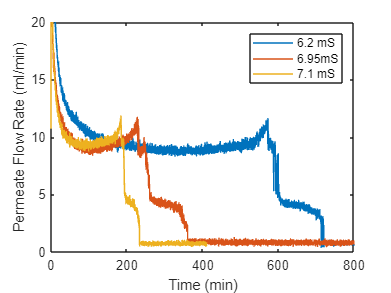

clf;
plot(batch16.time_list(1:end-1)/60, batch16.permeate_flowrate_filtered, batch12.time_list(1:end-1)/60, batch12.permeate_flowrate_filtered, ...
    batch14.time_list(1:end-1)/60, batch14.permeate_flowrate_filtered)
legend('6.2 mS', '6.95mS','7.1 mS')
ylabel('Permeate Flow Rate (ml/min)')
xlabel('Time (min)')
xlim([0, 800])
ylim([0 20])